# Linear Control Design II - Group Work Problem Module 2

## Description

In Figure 1 an electro-mechanical system is illustrated. The mechanical part is composed of a flexible structure buit by three masses interconnected by flexible beams. The electrical part is composed of a pair of electromagnets. The lateral movements of the lower mass is coupled to the pair of electromagnets by means of the electromagnetic forces generated in the small gap illustrated in Figure 2. It means there is no mechanical contact between the two parts. The main goal is: a) to build an electro-mechanical model based on simplifying assumptions; b) to build a mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday; c) to build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t),\,\,x_2(t),\,\,x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$; d) investigate the vibrations of the structure when different initial conditions and inputs are present.

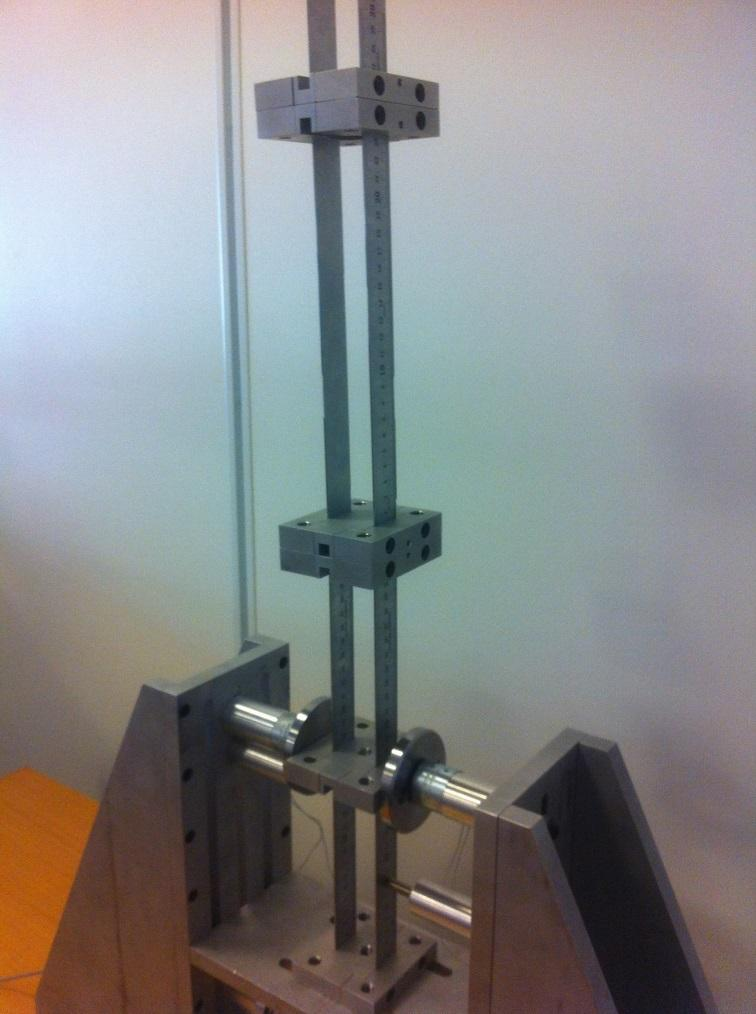


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


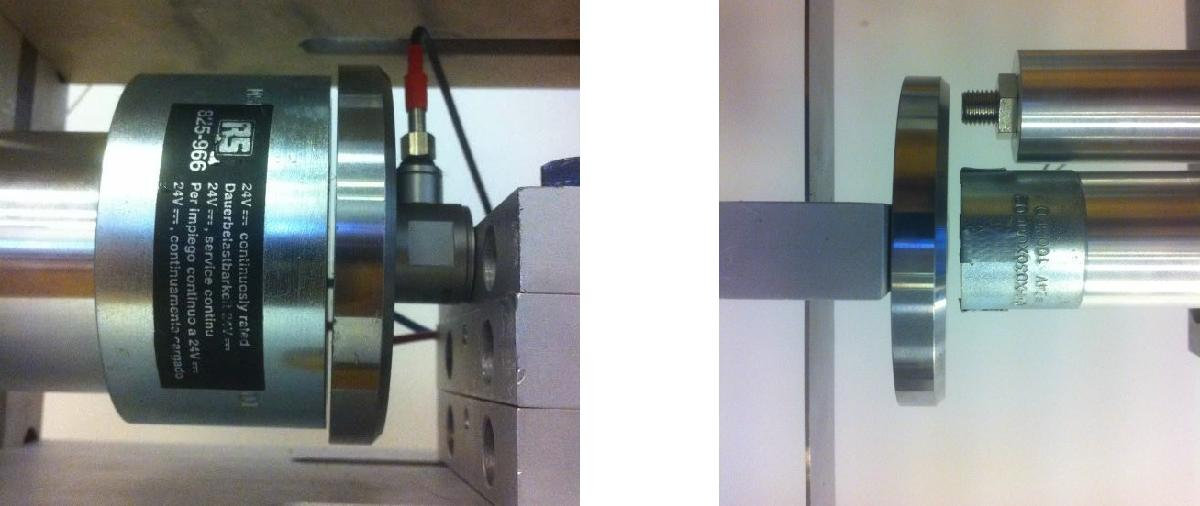


$$(a)\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad (b)$$



$$Figure\,2:\,The\,electro parts:\,(a)\,one\,single\,electromagnet\,and\,the\,gap\,where\,the\\ electromagnetic\,force\,will\,be\,generated\,by\,the\,input\,voltage\,u(t);\,(b)\,electromagnetic\\ actuator\,and\,eddy-current\,displacement\,sensor\,using\,to\,control\,and\,to\,measure\,the\\ lateral\,movements\,of\,the\,lower\,mass.$$


For the simulations the following parameters should be used.

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

R = 148.2;
L = 800e-3; % [H]

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

K1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
K2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
K3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3
k1=K1;k2=K2;k3=K3;

Ki5 = 22.4;
Ks5 = -313.6;

Ki3 = 37.33;
Ks3 = -871.11;

Ki2 = 56;
Ks2 = -1.96e3;

Ki1 = 112;
Ks1 = -7.84e3;

Where $Ki\#$ indicates the magnitude of the linearized force dependent on current change when the air gap $s_0$=$\#$ mm.

**Problem 1**

Build an electro-mechanical model based on simplifying assumptions.

% Your solution goes here:
% Derive by hand and/or upload picture


**Problem 2**

Build the mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday, based on the electro-mechanical model and simplifying assumptions done in problem 1.Use as main variables the  three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.

% Your solution goes here:
% Derive by hand and/or upload picture


**Problem 3**

Build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.  

% Your solution goes here:
% Fill in your code or upload picture


**Problem 4**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results.

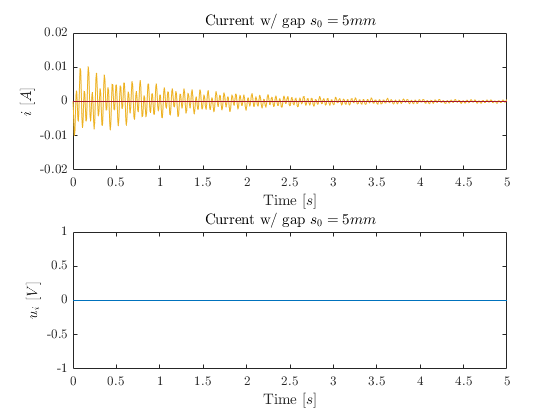

% Your solution goes here:
u_0 = 0;
x_0 = [0 0 0.001 0 0 0 0];

Ki = Ki5;
Ks = Ks5;

sim('electroMagneticModel.slx');

time = i.time;
figure(1)
subplot(2,1,1)
plot(time, i.data);
xlabel('Time $[s]$')
ylabel(['$i$ $[A]$'])
title('Current w/ gap $s_0=5 mm$')
subplot(2,1,2)
plot(time, u.data);
xlabel('Time $[s]$')
ylabel(['$u_i$ $[V]$'])
title('Current w/ gap $s_0=5 mm$')

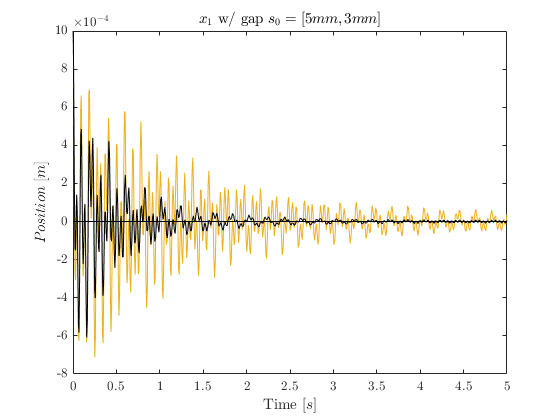

figure(2)
plot(time, x1.data);
xlabel('Time $[s]$')
ylabel(['$Position$ $[m]$'])
title('$x_1$ w/ gap $s_0= [5 mm, 3 mm]$')
figure(3)
plot(time, x2.data);
xlabel('Time $[s]$')
ylabel(['$Position$ $[m]$'])
title('$x_2$ w/ gap $s_0=[5 mm, 3 mm]$')
figure(4)
plot(time, x3.data);
xlabel('Time $[s]$')
ylabel(['$Position$ $[m]$'])
title('$x_3$ w/ gap $s_0=[5 mm, 3 mm]$')

Ki = Ki3;
Ks = Ks3;
sim('electroMagneticModel.slx');
time = i.Time;

figure(2)
hold on
plot(time, x1.Data,'k')
figure(3)
hold on
plot(time, x2.Data,'k')
figure(4)
hold on
plot(time, x3.Data,'k')
Ki = Ki3;
Ks = Ks3;
sim('electroMagneticModel.slx');
time = i.Time;
figure(2)
hold on
plot(time, x1.Data,'k')

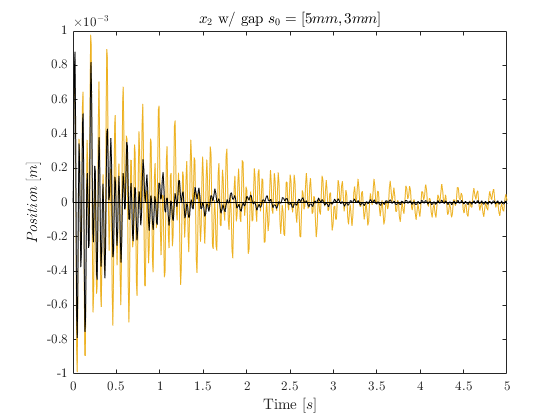

figure(3)
hold on
plot(time, x2.Data,'k')

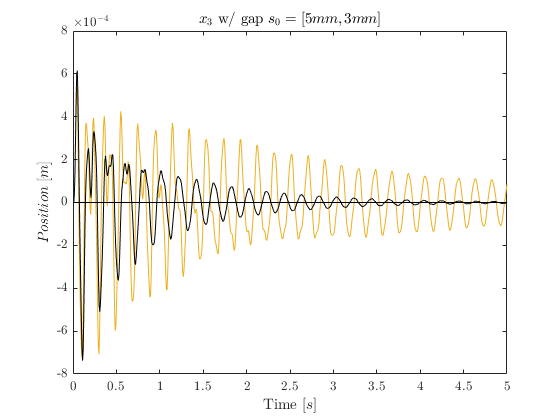

figure(4)
hold on
plot(time, x3.Data,'k')

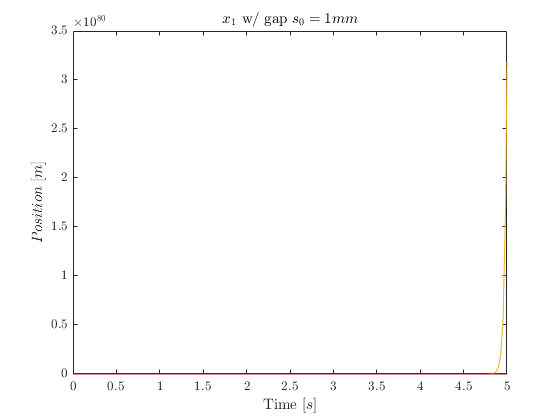

Ki = Ki1;
Ks = Ks1;
sim('electroMagneticModel.slx');
time = i.Time;
figure
plot(time, x1.data);
xlabel('Time $[s]$')
ylabel(['$Position$ $[m]$'])
title('$x_1$ w/ gap $s_0= 1 mm$')

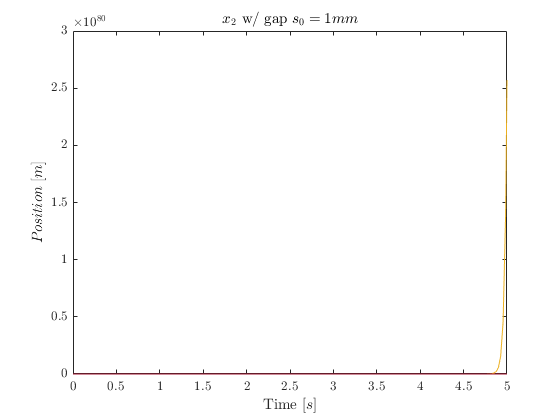

figure
plot(time, x2.data);
xlabel('Time $[s]$')
ylabel(['$Position$ $[m]$'])
title('$x_2$ w/ gap $s_0= 1 mm$')

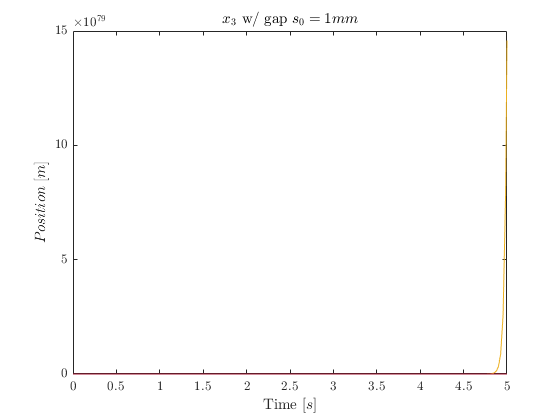

figure
plot(time, x3.data);
xlabel('Time $[s]$')
ylabel(['$Position$ $[m]$'])
title('$x_3$ w/ gap $s_0= 1 mm$')

**Problem 5**

What is the maximum lateral displacement experienced by the three masses when an initial condition of velocity of 5 mm/s acts on mass 3, assuming $s_0$=2 mm?

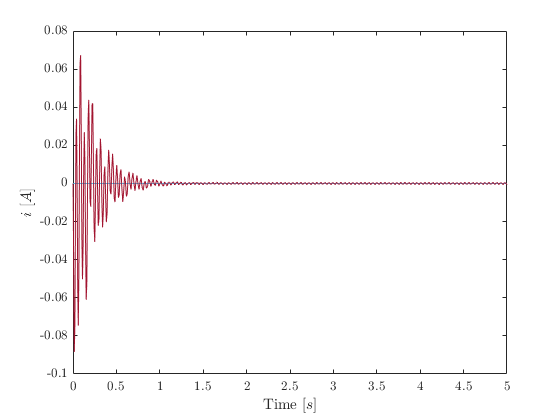

% Your solution goes here:
x_0 = [0 0 0 0 0 0 0.005];
Ki = Ki2;
Ks = Ks2;
sim('electroMagneticModel.slx')
time = i.Time;
figure
plot(time, i.Data)
xlabel('Time $[s]$')
ylabel('$i$ $[A]$')

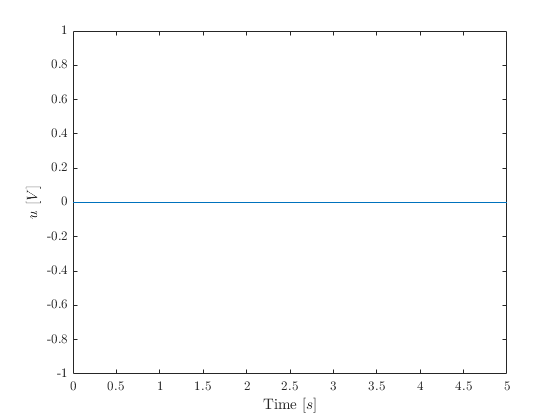

figure
plot(time, u.Data)
xlabel('Time $[s]$')
ylabel('$u$ $[V]$')

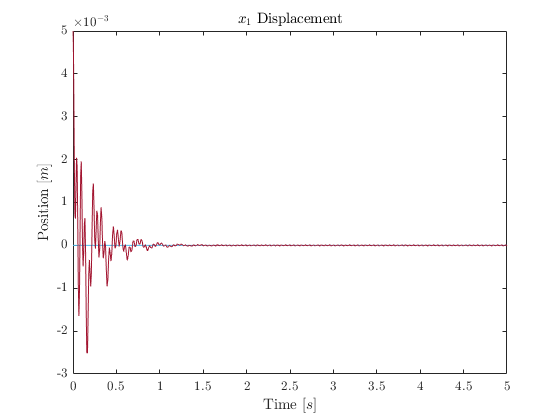

figure
plot(time, x1.Data)
xlabel('Time $[s]$')
ylabel('Position $[m]$')
title('$x_1$ Displacement')

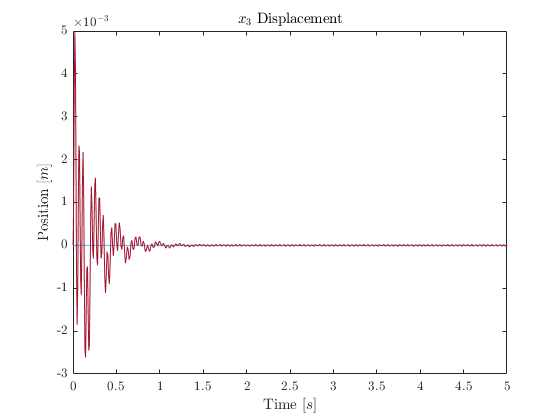

figure
plot(time, x2.Data)
xlabel('Time $[s]$')
ylabel('Position $[m]$')
title('$x_2$ Displacement')
title('$x_3$ Displacement')

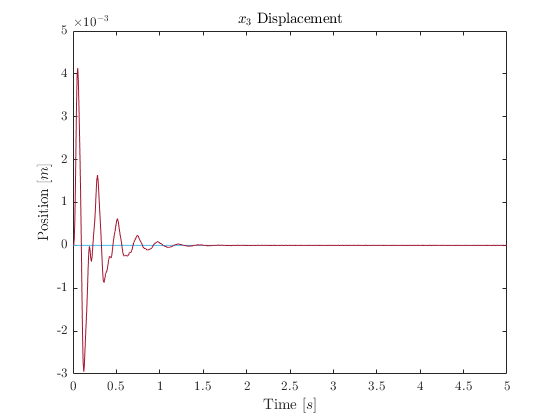

figure
plot(time, x3.Data)
xlabel('Time $[s]$')
ylabel('Position $[m]$')
title('$x_3$ Displacement')

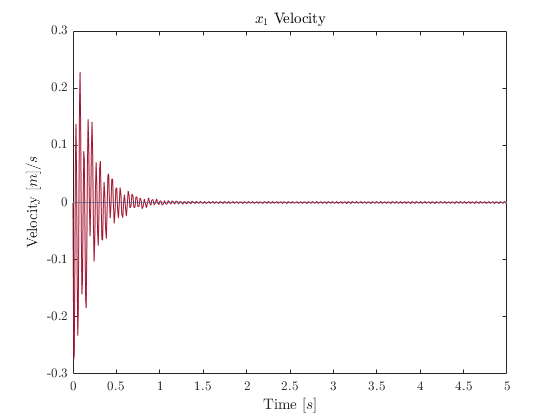

figure
plot(time, x1d.Data)
xlabel('Time $[s]$')
ylabel('Velocity $[m]/s$')
title('$x_1$ Velocity')

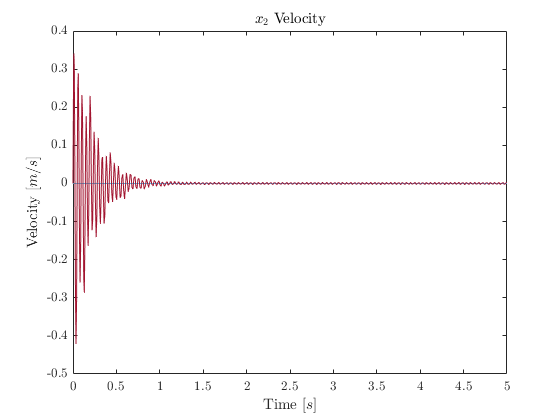

figure
plot(time, x2d.Data)
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')
title('$x_2$ Velocity')

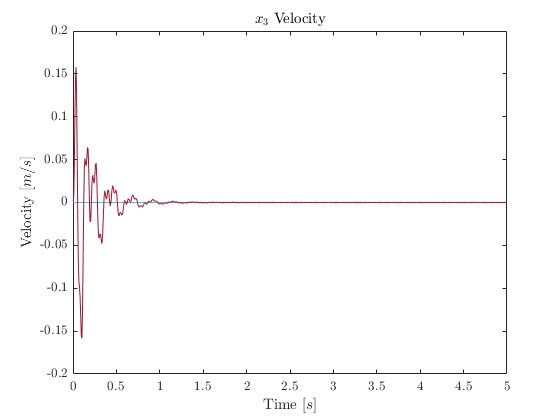

figure
plot(time, x3d.Data)
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')
title('$x_3$ Velocity')

**Problem 6**

A step function $u(t)$=10 V is send to the electromagnets, assuming all initial conditions of lateral displacement, velocity and current nill. How will the three masses vibrate and how will the current change, i.e. amplitudes and frequencies.

% Your solution goes here:
x_0 = [0 0 0 0 0 0 0];

x_0 =      0     0     0     0     0     0     0


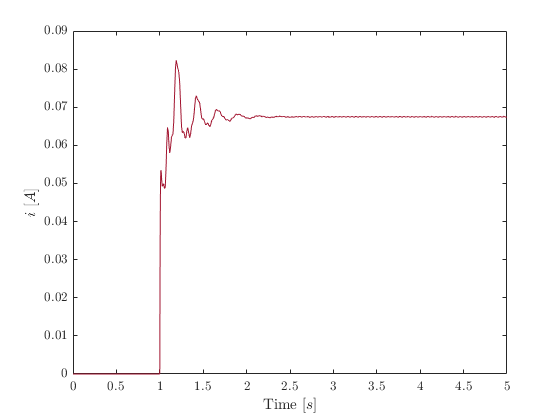

u_0 = 10;
sim('electroMagneticModel.slx')
time = i.Time;
figure
plot(time, i.Data)
xlabel('Time $[s]$')
ylabel('$i$ $[A]$')

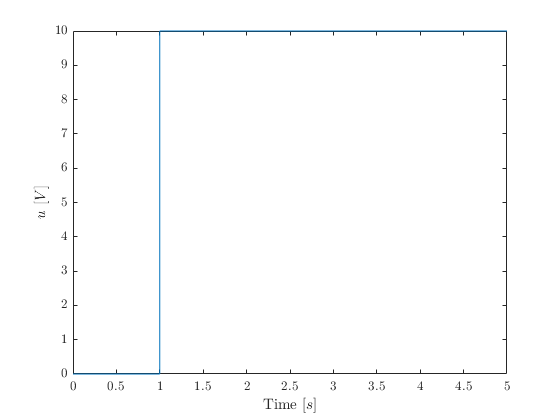

figure
plot(time, u.Data)
xlabel('Time $[s]$')
ylabel('$u$ $[V]$')

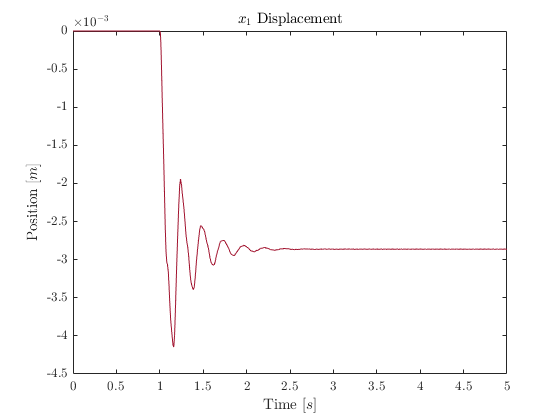

figure
plot(time, x1.Data)
xlabel('Time $[s]$')
ylabel('Position $[m]$')
title('$x_1$ Displacement')

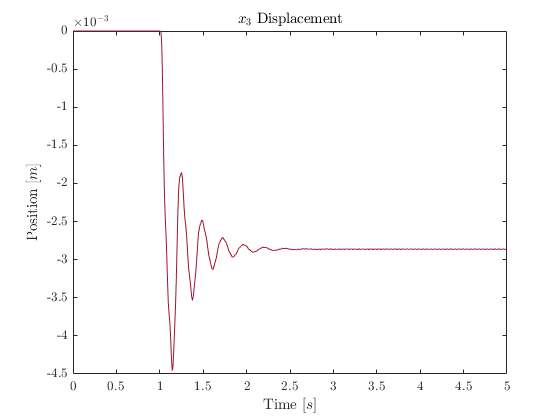

figure
plot(time, x2.Data)
xlabel('Time $[s]$')
ylabel('Position $[m]$')
title('$x_2$ Displacement')
title('$x_3$ Displacement')

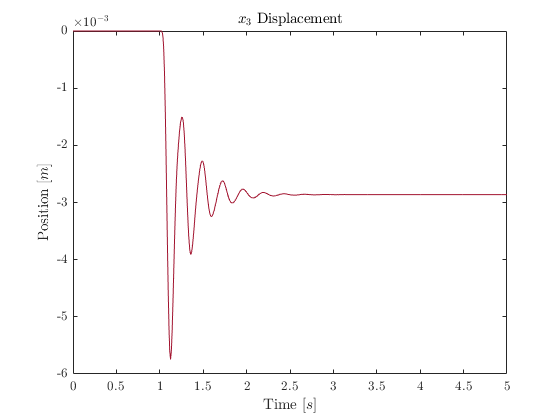

figure
plot(time, x3.Data)
xlabel('Time $[s]$')
ylabel('Position $[m]$')
title('$x_3$ Displacement')

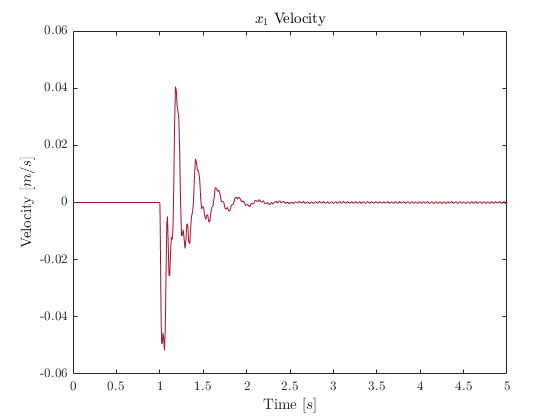

figure
plot(time, x1d.Data)
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')
title('$x_1$ Velocity')

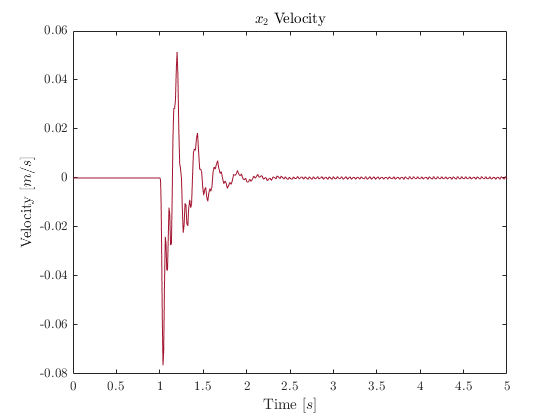

figure
plot(time, x2d.Data)
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')
title('$x_2$ Velocity')

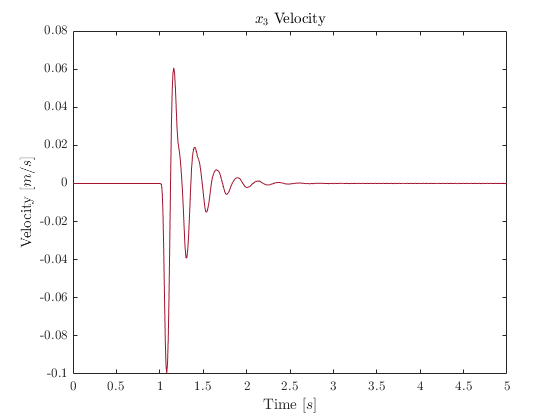

figure
plot(time, x3d.Data)
xlabel('Time $[s]$')
ylabel('Velocity $[m/s]$')
title('$x_3$ Velocity')